# Detección de *blobs* con filtro NLoG

## Importación y limpiado de la imagen

clc, clear, close all

% Leemos el mapa de bits que sale del microscopio
I = double(imread('../tiltser_W.tif',6));

% Normalizamos
I = I/max(max(I));

% Recortamos región de la izquierda 
% (Es heurístico pero ayuda a mejorar la calidad de la convolución)
[~,m] = size(I);
I = I(:,9:m);

% Limpiamos el ruido de la imagen con SVD (escogemos menor r posible)
r = 3;
[U,S,V] = svd(I);
If = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';

% Limpiamos el ruido de la imagen con FFT
thresh = 0.01;
Yt = fft2(I);
Max = max(max(abs(Yt)));
ind = abs(Yt) > thresh*Max;
Atlow = single(Yt .* ind);
Ilow = double(ifft2(Atlow));

## Aplicamos el algoritmo

Definimos inicialmente una lista con los sigmas que vamos a utilizar:

sgm_list = [2.0];

Llamamos a la función que aplica el algoritmo de detección de *blobs*:

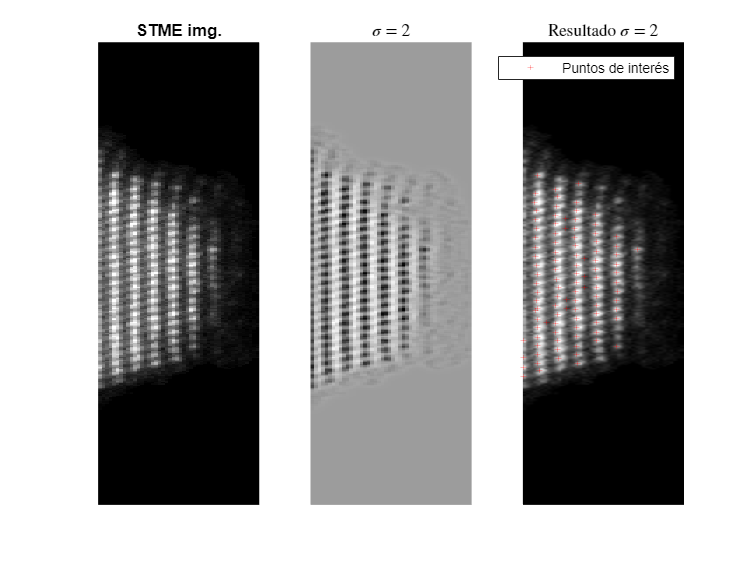

% Para la imagen sin filtrar
figure(1), clf 
blobDetector(I,sgm_list,0.0495,4,"");

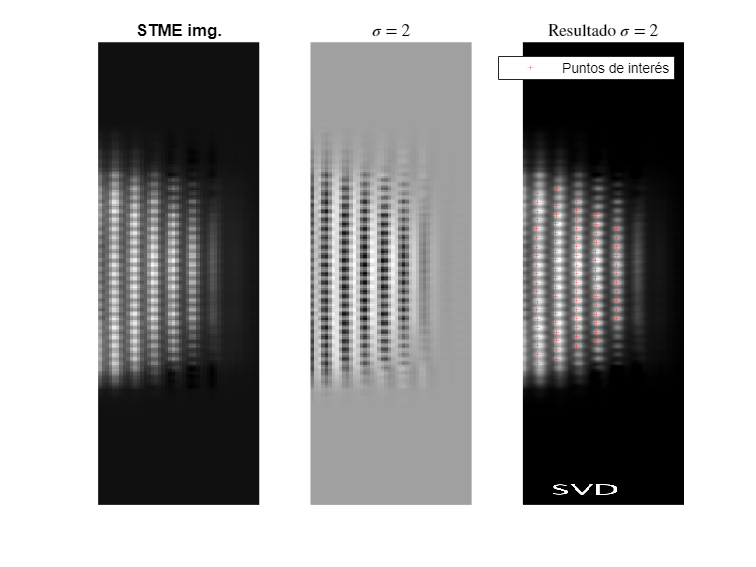


% Para la imagen filtrada por SVD
figure(2), clf 
blobDetector(If,sgm_list,0.0495,4,"SVD");

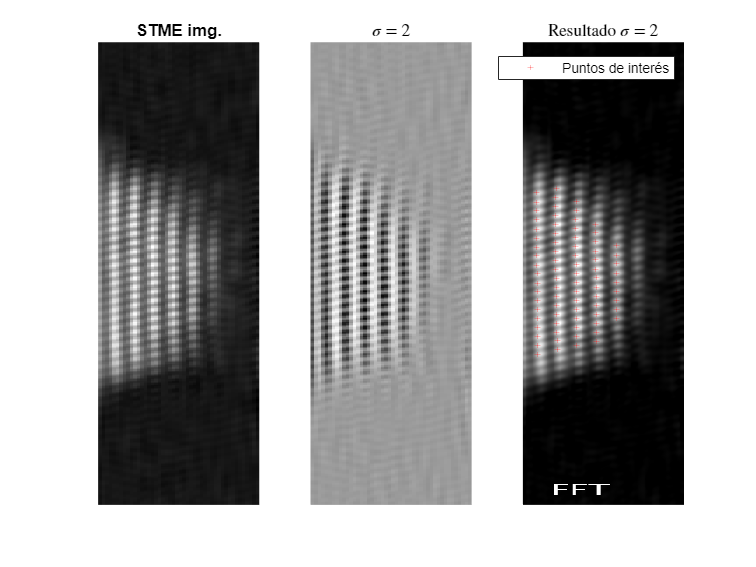


% Para la imagen filtrada por FFT
figure(3), clf 
blobDetector(Ilow,sgm_list,0.0495,4,"FFT");

Actualmente el umbral $\delta
$ se asigna de forma manual. Lo ideal sería poder determinarlo de forma automática en virtud de la calidad de la calidad de la imagen. De este modo el algoritmo sería mucho menos heurístico.